# Windmill Performance as Opposed to Temperature and Ambient Wind Speed

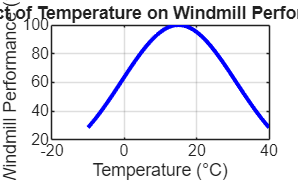

%{
ES115 Windmill Performance Plot Project - Project 2
Author: Jack O'charek
Date: 4-26-26
Purpose:
    Demonstrate the effect which temperature and wind speed have on the
    performance of a windmill.
Input:
    N/A
Output:
    Two plots will be created, one showing ambient temperature as opposed to
    windmill performance, and the other showing wind speed as opposed to
    windmill performance.
Engineering Algorithms:
    Clear screen and delete all variables
    Define ranges for temperature and wind speed, in celcius and m/s
    Define ideal conditions
    Define metric sensitivity
    Define relation between performance and temperature
    Set range of windmill performance (same for both relations)
    Define relation between performance and wind speed
    Plot temperature and windmill performance relation
    Plot wind speed and windmill performance relation
%}
clc;
clear;
close all;
temperature = -10:1:40;     
wind_speed = 0:0.5:25;      
T_ideal = 15;               
W_ideal = 12;               
temp_sensitivity = 0.002; 
wind_sensitivity = 0.01;    
perf_temp = 100 * exp(-temp_sensitivity * (temperature - T_ideal).^2);
perf_temp = max(0, min(100, perf_temp));
perf_wind = 100 * exp(-wind_sensitivity * (wind_speed - W_ideal).^2);
perf_wind = max(0, min(100, perf_wind));
figure;
plot(temperature, perf_temp, 'b', 'LineWidth', 2);
grid on;
xlabel('Temperature (°C)');
ylabel('Windmill Performance (%)');
title('Effect of Temperature on Windmill Performance');

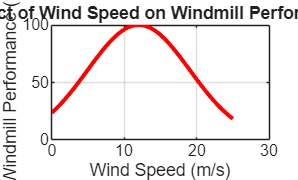

figure;
plot(wind_speed, perf_wind, 'r', 'LineWidth', 2);
grid on;
xlabel('Wind Speed (m/s)');
ylabel('Windmill Performance (%)');
title('Effect of Wind Speed on Windmill Performance');